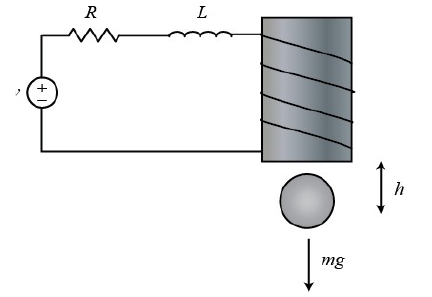

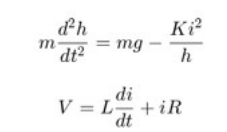

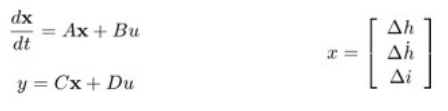

clc; clear; close all;
m = 0.05;    % kg;
K = 0.0001;
Li = 0.01;    % H;
R = 1;       % Ohm;
g = 9.81;    % m/s^2.

% heq = K*ieq^2/(m*g)
heq = 0.01;           % m. En donde se linealiza
ieq = sqrt(heq*m*g/K) % A

ieq = 7.0036

A = [ 0 1 0; 980 0 -2.8; 0 0 -100 ];
Aobs = [ 0 1 0; 900 0 -3.0; 0 0 -110 ];
B = [ 0 0 100 ]';
Bobs = [ 0 0 80 ]';

- Defina la matriz C.

C = [1 0 0]

C =      1     0     0


D = 0;

- Determine el valor de K y kr. Utilice el método de Ackerman

p1 = - 20 + 20*i;
p2 = - 20 - 20*i;
p3 = - 20;

W  = [Bobs Aobs*Bobs Aobs^2*Bobs];
if rank(W) == 3
    disp('Alcanzable y por lo tanto completamente controlable');
else
    disp('No es completamente controlable y el rango es:');
    disp(rank(W));
end

Alcanzable y por lo tanto completamente controlable


% Aobs = A;
% Bobs = B;
K  = acker(Aobs, Bobs, [p1 p2 p3])

K =  -291.6667  -10.4167   -0.6250


kr   = 1/(C*(-(Aobs-Bobs*K)\Bobs))

kr = -66.6667

- Mida el valor del sobrepico y el tiempo de establecimiento de y

out   = sim('Ejercicio6_sim_sinOBS.slx');
tdh   = out.dh.time;
dh    = out.dh.signals.values;

tddh   = out.ddh.time;
ddh    = out.ddh.signals.values;

tdi     = out.di.time;
di      = out.di.signals.values;

sobrepico    = (max(abs(dh))-abs(dh(end)))*100/abs(dh(end))

sobrepico = 28.7939

mask         = abs(dh-dh(end)) < 0.02;
idx          = find(~mask);
settlingtime = tdh(idx(end)+1)

settlingtime = 1.4403

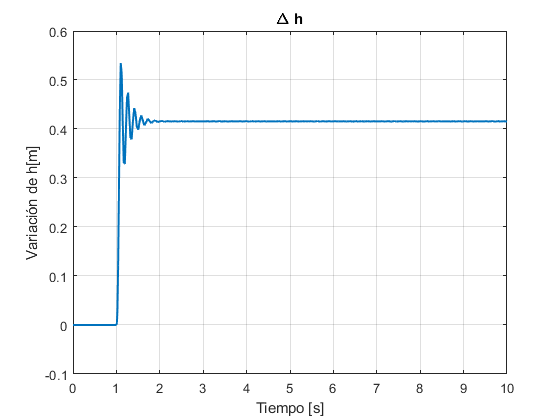


figure;
plot(tdh, dh, 'LineWidth', 1.5);
xlabel('Tiempo [s]');
ylabel('Variación de h[m]');
title('\Delta h');
grid on;

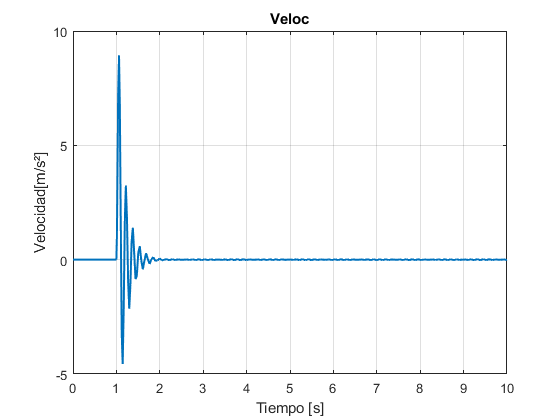


figure;
plot(tddh, ddh, 'LineWidth', 1.5);
xlabel('Tiempo [s]');
ylabel('Velocidad[m/s²]');
title('Veloc');
grid on;

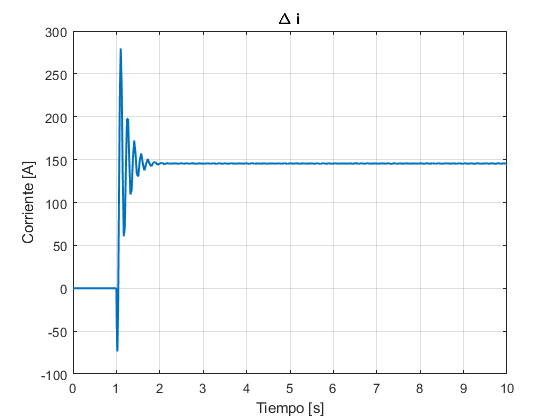


figure;
plot(tdi, di, 'LineWidth', 1.5);
xlabel('Tiempo [s]');
ylabel('Corriente [A]');
title('\Delta i');
grid on;

- Desarrolle un observador para este sistema. Cierre el bucle de realimentación a través del observador.

if (rank([C*eye(3); C*A; C*A^2]) == 3)
    disp('Es completamente observable.')
else
    disp('No es completamente observable.')
end

Es completamente observable.


L = place(Aobs.', C.', [-40, -85, -110]); % En realidad se determina L^t
L = L.'

L = 	1.0e+03 *

    0.1250
    4.3000
         0


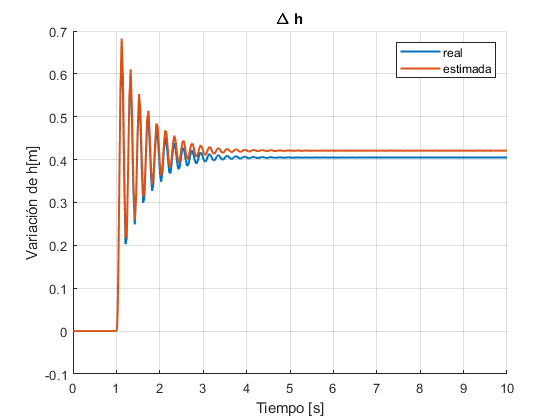

out   = sim('Ejercicio6_sim.slx');
tdh   = out.dh.time;
dh    = out.dh.signals.values;

tddh   = out.ddh.time;
ddh    = out.ddh.signals.values;

tdi     = out.di.time;
di      = out.di.signals.values;

tdho   = out.dho.time;
dho    = out.dho.signals.values;

tddho   = out.ddho.time;
ddho    = out.ddho.signals.values;

tdio     = out.dio.time;
dio      = out.dio.signals.values;

figure;hold on;
plot(tdh, dh, 'LineWidth', 1.5);
plot(tdho, dho, 'LineWidth', 1.5);
legend('real', 'estimada');
xlabel('Tiempo [s]');
ylabel('Variación de h[m]');
title('\Delta h');
grid on;

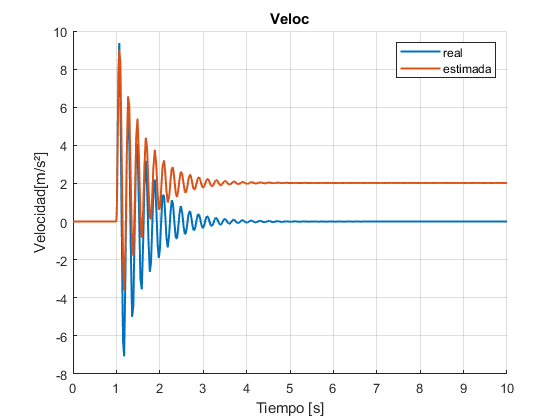

figure;hold on;
plot(tddh, ddh, 'LineWidth', 1.5);
plot(tddho, ddho, 'LineWidth', 1.5);
legend('real', 'estimada');
xlabel('Tiempo [s]');
ylabel('Velocidad[m/s²]');
title('Veloc');
grid on;

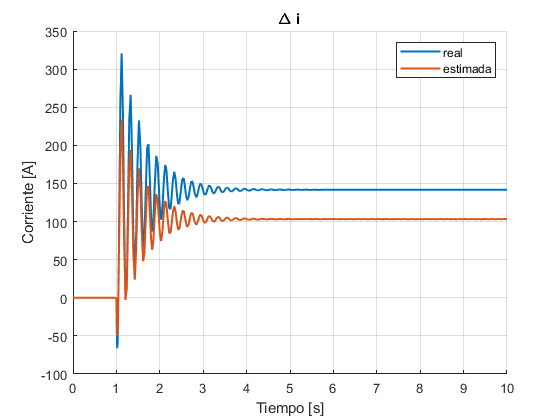


figure;hold on;
plot(tdi, di, 'LineWidth', 1.5);
plot(tdio, dio, 'LineWidth', 1.5);
legend('real', 'estimada');
xlabel('Tiempo [s]');
ylabel('Corriente [A]');
title('\Delta i');
grid on;